# Homework 7

**By Ari Porad, May 2nd 2021**

**Quantitative Engineering Analysis 2**

## Exercise 29.2

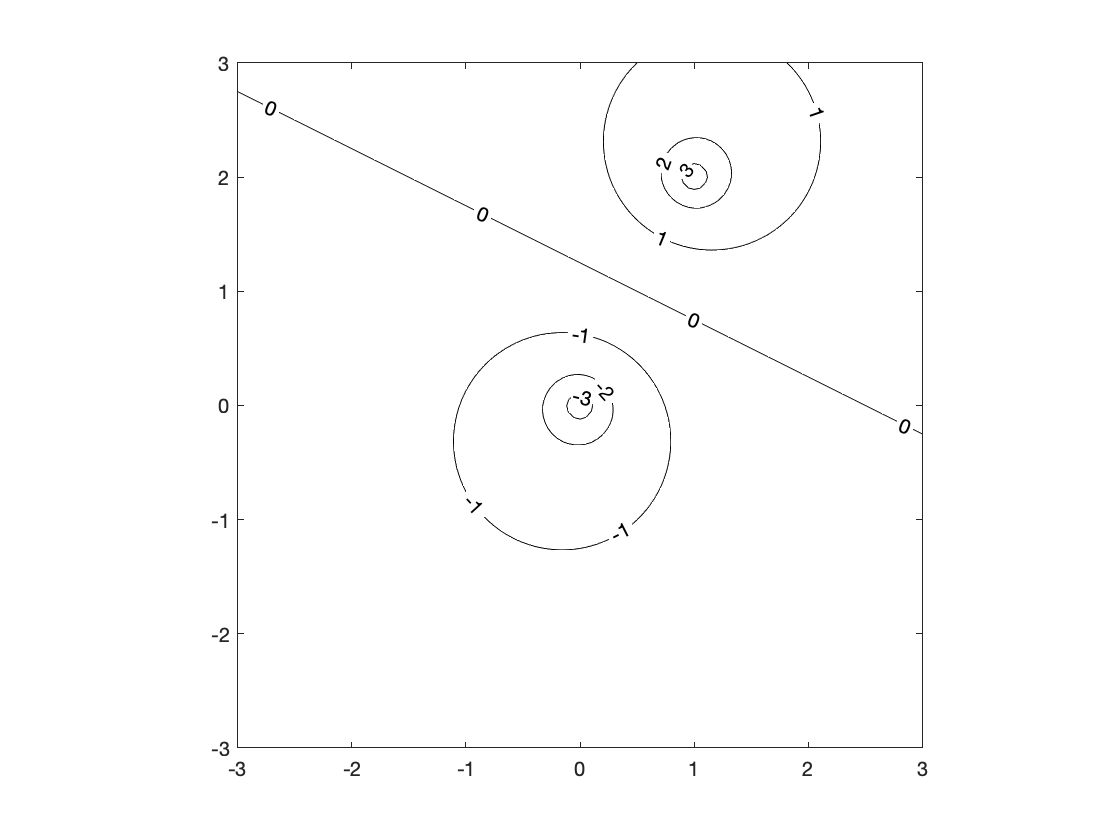

[x, y] = meshgrid(-3:0.05:3, -3:0.05:3);
v = log(sqrt(x.^2 + y.^2)) - log(sqrt((x - 1).^2 + (y - 2).^2));
contour(x,y,v,'k','ShowText',"on");
axis equal;

## Exercise 29.3

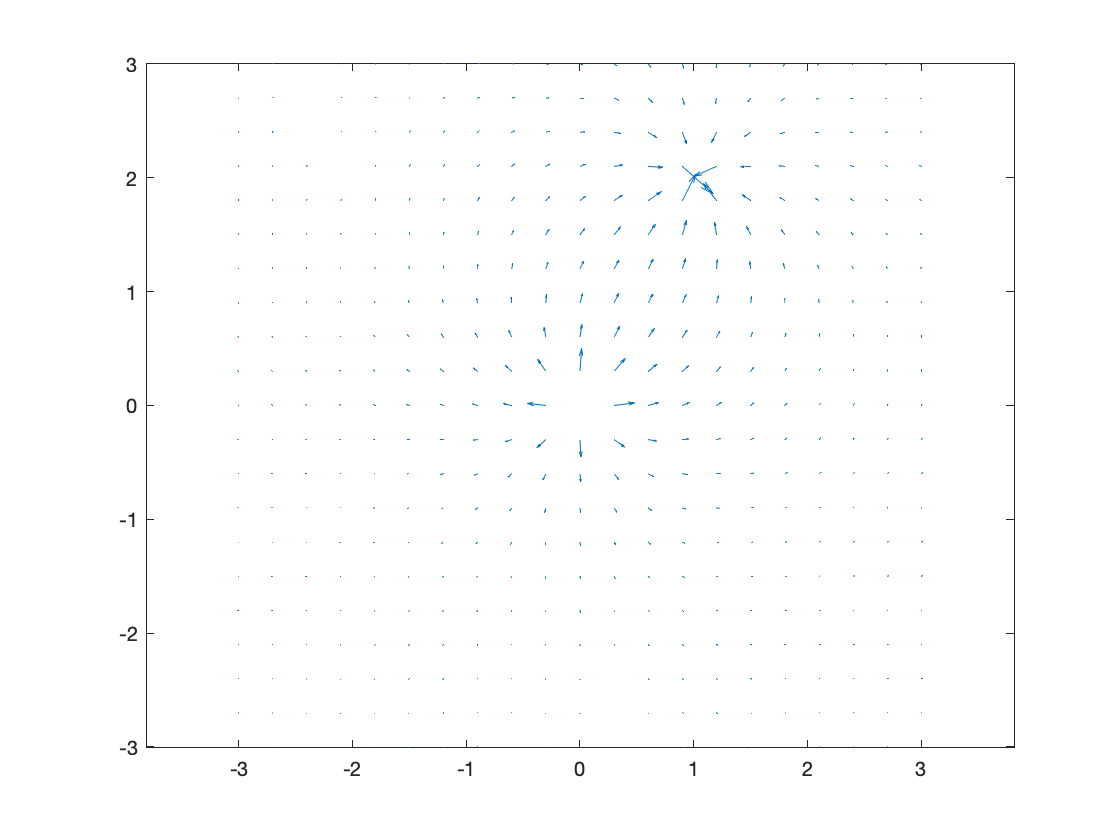

[x, y] = meshgrid(-3:0.3:3, -3:0.3:3);
fx = x./(x.^2 + y.^2) - (x-1)./((x-1).^2 + (y-2).^2);
fy = y./(x.^2 + y.^2) - (y-2)./((x-1).^2 + (y-2).^2);
quiver(x,y,fx,fy);
axis equal;

## Exercise 29.4

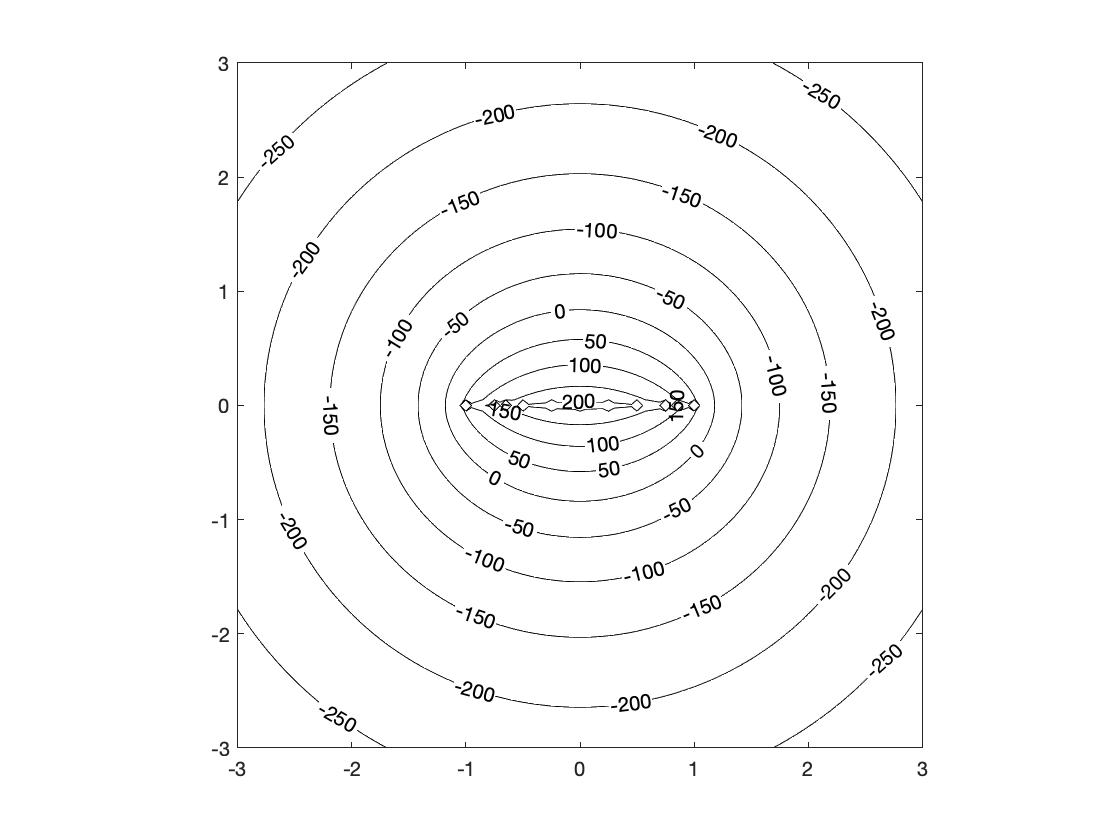

% #2: The Contours
[x,y] = meshgrid(-3:0.05:3, -3:0.05:3);
v = 0;
for a = -1:0.01:1
    v = v - log(sqrt((x-a).^2 + y.^2));
end
contour(x,y,v,'k', 'ShowText', 'on');
axis equal;

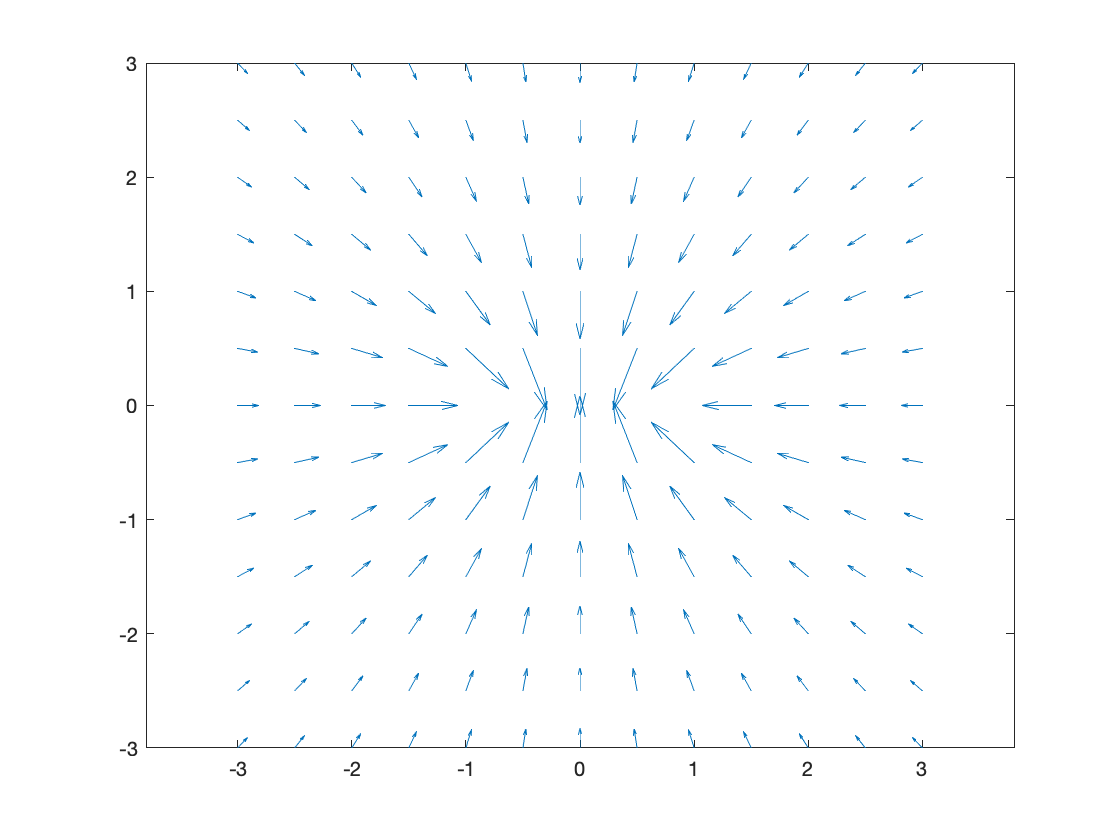


% #3: The Vector Field
figure; clf;
[x,y] = meshgrid(-3:0.5:3, -3:0.5:3);
fx = 0;
fy = 0;

for a = -1:0.01:1
    fx = fx - ((x - a) ./ ((x - a).^2 + y.^2));
    fy = fy - (y ./ ((x - a).^2 + y.^2));
end

quiver(x, y, fx, fy);
axis equal;

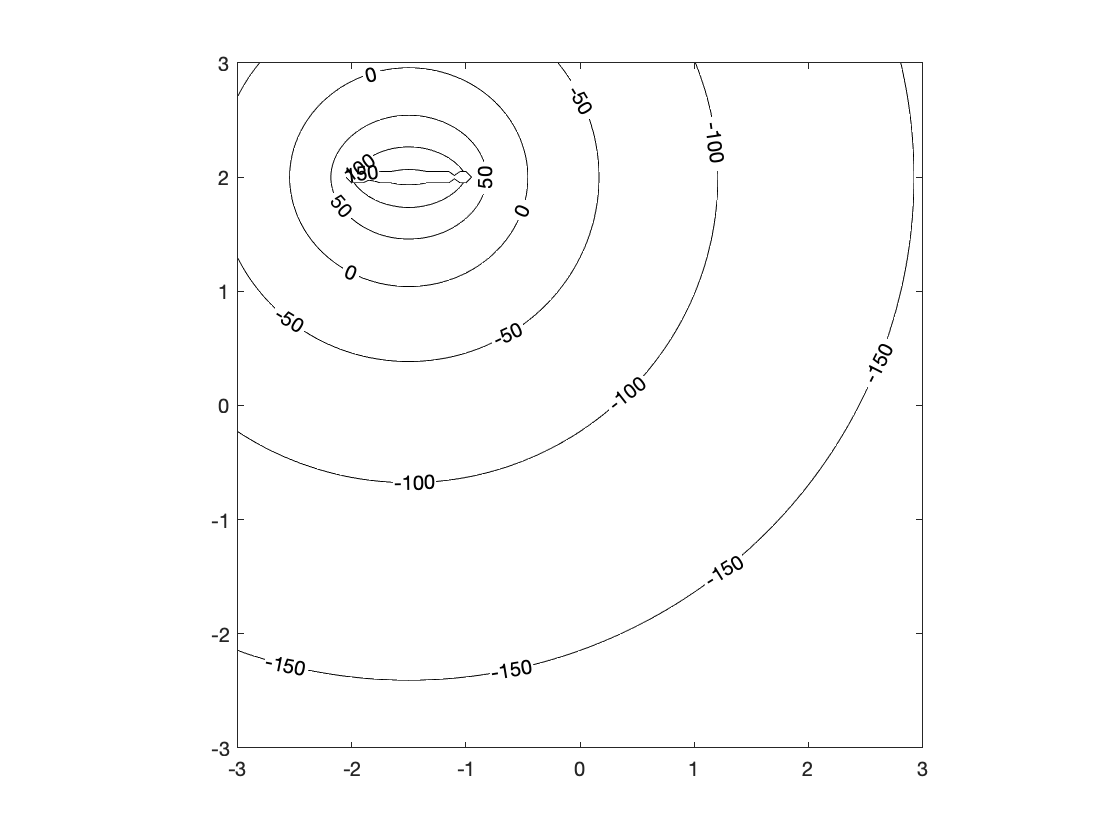


% #3: The Contours, Translated
figure; clf;
[x,y] = meshgrid(-3:0.05:3, -3:0.05:3);
v = 0;
for a = -2:0.01:-1
    v = v - log(sqrt((x-a).^2 + (y-2).^2));
end
contour(x,y,v,'k', 'ShowText', 'on');
axis equal;

## Exercise 29.5

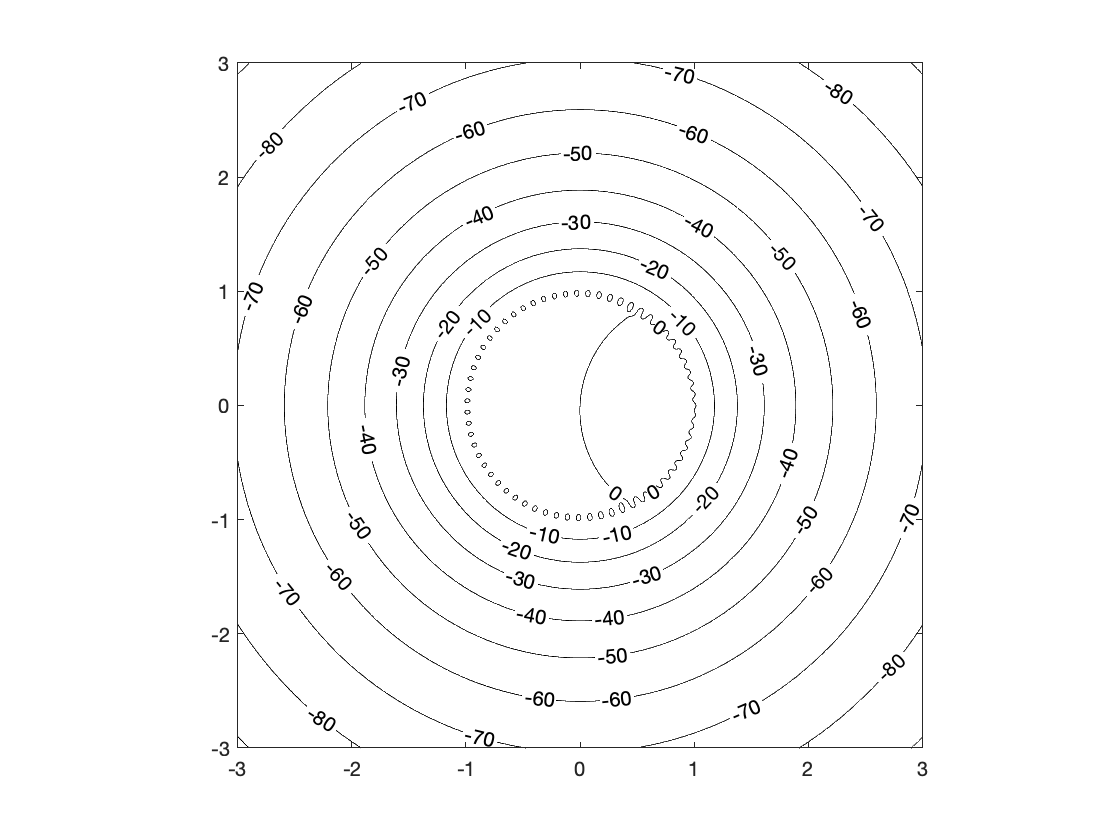

% #2: Potential Field Contours
[x, y] = meshgrid(-3:0.01:3, -3:0.01:3);
v = 0;

for theta = 0:0.1:2*pi
    a = cos(theta);
    b = sin(theta);
    v = v - log(sqrt((x-a).^2 + (y-b).^2));
end

contour(x, y, v, 'k', 'ShowText', 'on'); axis equal;

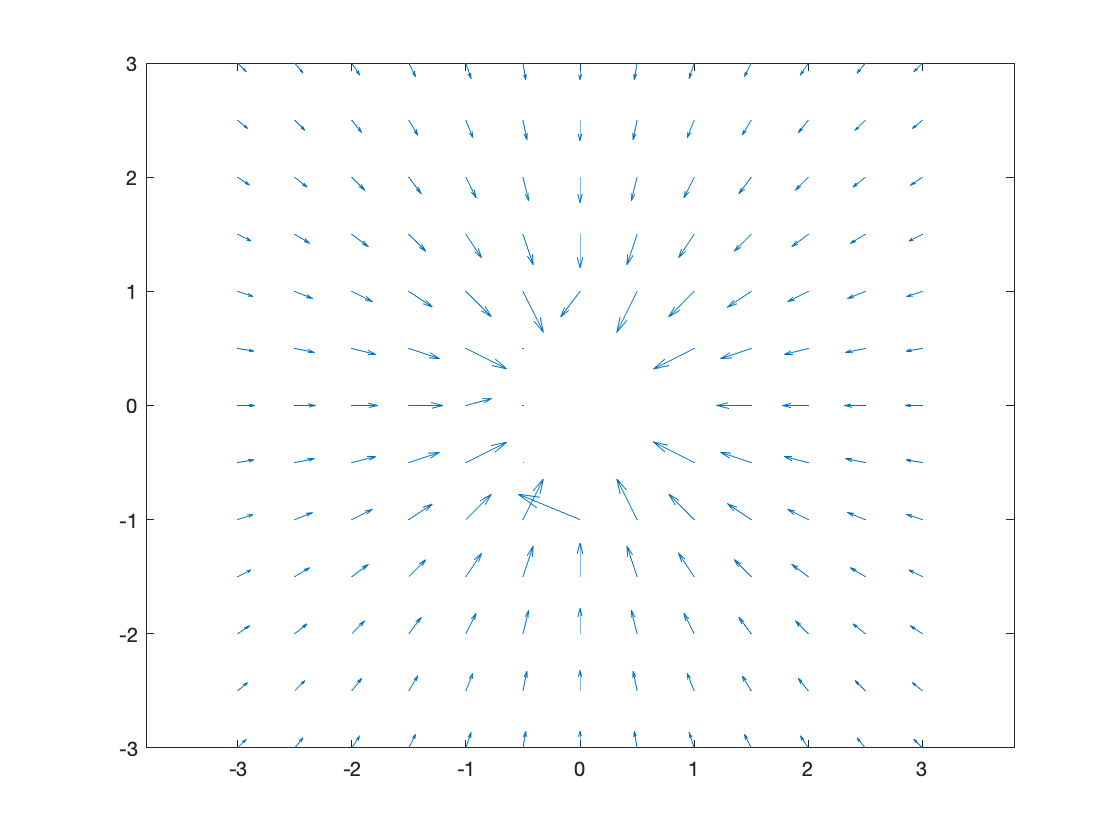


% #3: Gradient Vector Field
figure; clf;
[x,y] = meshgrid(-3:0.5:3, -3:0.5:3);
fx = 0;
fy = 0;

for theta = 0:0.1:2*pi
    a = cos(theta);
    b = sin(theta);
    fx = fx - ((x - a) ./ ((x - a).^2 + (y - b).^2));
    fy = fy - ((y - b) ./ ((x - a).^2 + (y - b).^2));
end

quiver(x, y, fx, fy);
axis equal;

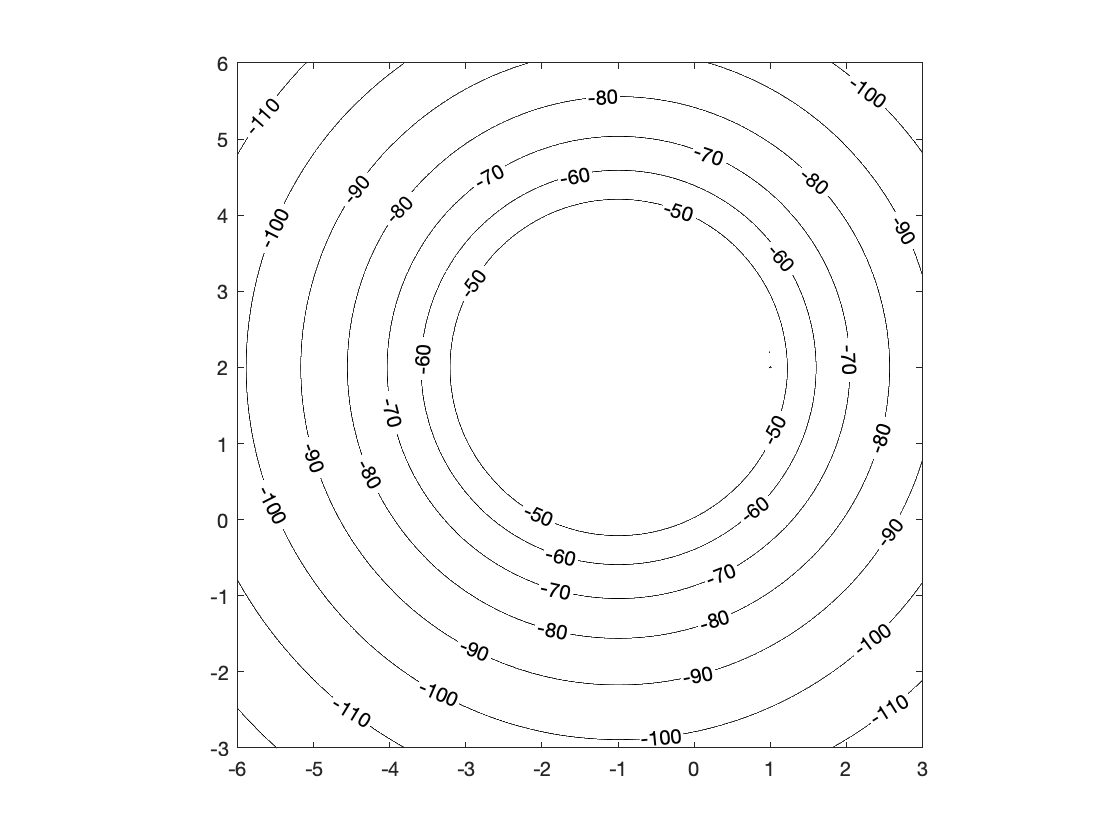


% #4: Scaled and Translated
figure; clf;
[x, y] = meshgrid(-6:0.01:3, -3:0.01:6);
v = 0;

for theta = 0:0.1:2*pi
    a = 2 * cos(theta);
    b = 2 * sin(theta);
    v = v - log(sqrt((x-a +1).^2 + (y-b -2).^2));
end

contour(x, y, v, 'k', 'ShowText', 'on'); axis equal;